close all

Define our problem (Slide 4):

global a b d   % for use in all helper functions below

a = 2;
b = 3;
d = 5;

## **HW1 Approach**

On HW1, we found C that minimizes distance experimentally, using "exhaustive search"

C = [0:.1:d];               % FREE VARIABLE
r1 = sqrt(a^2 + C.^2);
r2 = sqrt(b^2 + (d-C).^2);
D = r1 + r2;                % COST FUNCTION
C_star = C(D == min(D))     % MINIMUM

C_star = 2

## Calculus Approach

Define necessary conditions for a minimum and solve the resulting equations.

Symbolic Math Toolbox (Slide 5)

% symbolic equations solver
syms a b d c

rA = sqrt(a^2 + c^2),...
rB = sqrt(b^2 + (d - c)^2),...
D = rA + rB

$$rA = \sqrt{a^{2}+c^{2}}$$

$$rB = \sqrt{b^{2}+{\left(c-d\right)}^{2}}$$

$$D = \sqrt{a^{2}+c^{2}}+\sqrt{b^{2}+{\left(c-d\right)}^{2}}$$

Step 1: Compute 1st Derivative

dD_dC = diff(D,'c')

$$dD\_dC = \frac{c}{{\left(a^{2}+c^{2}\right)}^{0.5000}}+\frac{0.5000\,\left(2\,c-2\,d\right)}{{\left(b^{2}+{\left(c-d\right)}^{2}\right)}^{0.5000}}$$

If we had done this by hand, term by term:


$$\frac{\textrm{dD}}{\textrm{dC}}=\frac{dr_A }{\textrm{dC}}+\frac{dr_B }{\textrm{dC}}$$


drA_dC = diff(rA,'c'),...
drB_dC = diff(rB,'c')

$$drA\_dC = \frac{c}{{\left(a^{2}+c^{2}\right)}^{0.5000}}$$

$$drB\_dC = \frac{0.5000\,\left(2\,c-2\,d\right)}{{\left(b^{2}+{\left(c-d\right)}^{2}\right)}^{0.5000}}$$

% check
isequal(dD_dC, drA_dC + drB_dC)

ans = logical
   1


Step 2: Solve the equation for the necessary condition:

% substitute for our problem's parameter values
params.a = 2;
params.b = 3;
params.d = 5;
dD_dC = subs(dD_dC,params)

$$dD\_dC = \frac{c}{{\left(c^{2}+4\right)}^{0.5000}}+\frac{0.5000\,\left(2\,c-10\right)}{{\left({\left(c-5\right)}^{2}+9\right)}^{0.5000}}$$

% solve the equation for c
C_star = solve(dD_dC == 0)

$$C\_star = 2$$

% even easier, solve the original distance equation
D = subs(D,params)

$$D = \sqrt{c^{2}+4}+\sqrt{{\left(c-5\right)}^{2}+9}$$

C_star = solve(diff(D))

$$C\_star = 2$$

Step 3: Compute 2nd Derivative and check if it's positive

d2D_dC2 = diff(dD_dC,'c')

$$d2D\_dC2 = {\left({\left(c-5\right)}^{2}+9\right)}^{-0.5000}-\frac{c^{2}}{{\left(c^{2}+4\right)}^{1.5000}}-\frac{0.2500\,{\left(2\,c-10\right)}^{2}}{{\left({\left(c-5\right)}^{2}+9\right)}^{1.5000}}+{\left(c^{2}+4\right)}^{-0.5000}$$


% or
d2D_dC2_a = diff(D,'c',2)

$$d2D\_dC2\_a = {\left({\left(c-5\right)}^{2}+9\right)}^{-0.5000}-\frac{c^{2}}{{\left(c^{2}+4\right)}^{1.5000}}-\frac{0.2500\,{\left(2\,c-10\right)}^{2}}{{\left({\left(c-5\right)}^{2}+9\right)}^{1.5000}}+{\left(c^{2}+4\right)}^{-0.5000}$$

% check
isequal(d2D_dC2, d2D_dC2_a)

ans = logical
   1


% check if 2nd derivative is positive when C = C*
deriv2 = subs(d2D_dC2,'c',C_star)

$$deriv2 = 0.2946$$

double(deriv2) > 0

ans = logical
   1


$C^* =2$** is a minimum!**

Regular Old MATLAB

Assume we had computed the above analytic expressions manually. (Slide 6)

a = 2;
b = 3;
d = 5;
D = r1 + r2;
drA_dC = (1/2)*(1./sqrt(a^2 + C.^2)).*(2*C);
drB_dC = (1/2)*(1./sqrt(b^2 + (d-C).^2))*2.*(d-C)*(-1);
dD_dC = drA_dC + drB_dC;
plot(C,dD_dC,'b.');grid on; xlabel('C'); ylabel('dD/dC'); hold on;
yline(0);
zeroCrossing = find(dD_dC == 0)


zeroCrossing =

  1×0 empty double row vector



% round-off error!
zcIdx = find(dD_dC >= 0,1,'first');
[C(zcIdx-2:1:zcIdx);dD_dC(zcIdx-2:1:zcIdx)]

ans =     1.9000    2.0000    2.1000
   -0.0299   -0.0000    0.0291


C_star = C(zcIdx)

C_star = 2.1000

Easier to compute numeric 1st and 2nd derivatives...

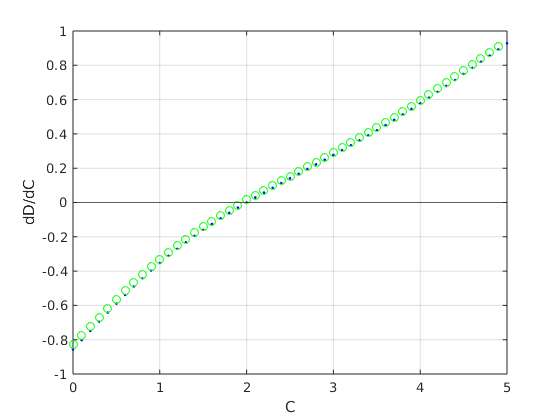

dD_dC = diff(D)./diff(C);
%plot(C,dD_dC,'g+') % note that diff returns array of length n-1 !
plot(C(1:end-1),dD_dC,'go');

zcIdx = find(dD_dC >= 0,1,'first');
[C(zcIdx-2:1:zcIdx);dD_dC(zcIdx-2:1:zcIdx)]

ans =     1.8000    1.9000    2.0000
   -0.0451   -0.0149    0.0146


C_star = C(zcIdx)

C_star = 2

Check the 2nd derivative

d2D = diff(D,2); % numerator only: equally spaced d2C creates div by zero!
[d2D(zcIdx-2:1:zcIdx+2); d2D(zcIdx-2:1:zcIdx+2) > 0]

ans =     0.0030    0.0029    0.0029    0.0028    0.0028
    1.0000    1.0000    1.0000    1.0000    1.0000


$C^* =2$** is a minimum!**

Using `fzero`

Define our problem:

a = 2;
b = 3;
d = 5;

Define an equation for our `necessaryCondition` that $\frac{\textrm{dD}}{\textrm{dC}}=0$

Q) When can we say that an iterative solution has converged to a solution?

A) When the difference between successive iterations, $\delta <\varepsilon$

initialGuesses = [-10; -2; 0; 1; 4; 5; 100];
X = zeros(size(initialGuesses));
FVAL = X;
EXIT = X;
for i=1:length(initialGuesses)
    [X(i), FVAL(i), EXIT(i)] = fzero(@necessaryCondition, initialGuesses(i));
end
fprintf('eps = %+13.6e\n', eps);

eps = +2.220446e-16


fprintf('exit   C*         error\n');

exit   C*         error


fprintf('----  ----    -------------\n');

----  ----    -------------


fprintf('%2d %8.3f %+15.6e\n', [EXIT, X, FVAL]');

 1    2.000   +1.110223e-16
 1    2.000   -1.110223e-16
 1    2.000   -1.110223e-16
 1    2.000   -1.110223e-16
 1    2.000   +1.110223e-16
 1    2.000   -1.110223e-16
 1    2.000   +1.110223e-16


`fzero`** found a solution, from multiple initial guesses, to **$\frac{\textrm{dD}}{\textrm{dC}}=0$ (**within **$\left.\varepsilon \right)$ **at **$C^* =2$ 

## Numerical Optimization Approach

UNCONSTRAINED OPTIMIZATION (Slide 7)

Define an objective function to minimize:

`dist = costFunc(C)`

Using `fminsearch`

% fminsearch
[C, minDist] = fminsearch(@costFunc, 0)

C = 2.0000

minDist = 7.0711

Using fmincon


% fmincon
[C, minDist] = fmincon(@costFunc, 0)


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


C = 2.0000

minDist = 7.0711

CONSTRAINED OPTIMIZATION (Slide 8)

Assume that Village A is located further from the river,

and that a massive cliff constrains where C can be.

a = 4;
[C, minDist] = fmincon(@costFunc, 0)


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


C = 2.8571

minDist = 8.6023

c = [0:.01:d];
plot(c,costFunc(c)); ylim([8 10]); hold on;
xline(C,'g'); yline(minDist,'g:');

% with weird constraints, dangerously high cliffs from 1.5 < C < 4.0
xline(1.5,'k','LineWidth',3);
xline(4,'k','LineWidth',3);

Solution occurs in the "forbidden zone!" How do we translate cost into the language of the solver?

Try linear inequalities: $\textrm{Ax}\le b$


$$\begin{array}{l}
C\le 1\ldotp 5\\
C\ge 4\ldotp 0\longrightarrow -C\le -4\ldotp 0
\end{array}$$


A = [1;
    -1]

A =      1
    -1


B = [1.5;
    -4]

B =     1.5000
   -4.0000



[c,minDist,exit,output] = fmincon(@costFunc, 0, A, B)


Converged to an infeasible point.

fmincon stopped because it is unable to find a point locally that satisfies
the constraints within the value of the constraint tolerance.

<stopping criteria details>


c = 2.7500

minDist = 8.6041

exit = -2

output = struct with fields:
         iterations: 12
          funcCount: 29
    constrviolation: 1.2500
           stepsize: 2.7068e-10
          algorithm: 'interior-point'
      firstorderopt: 0.0186
       cgiterations: 8
            message: '↵Converged to an infeasible point.↵↵fmincon stopped because it is unable to find a point locally that satisfies↵the constraints within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the constraint violations are locally stationary ↵but the relative maximum constraint violation, 3.125000e-01, exceeds↵options.ConstraintTolerance = 1.000000e-06.↵↵'


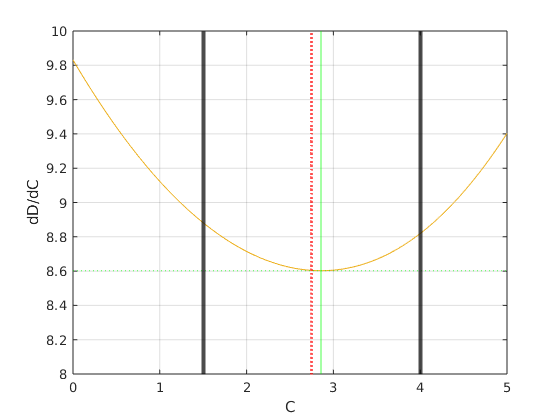

% unable to find a point locally that satisfies
% the constraints: c=2.75, D=8.8604
xline(c,'r:','LineWidth',2); %yline(minDist,'g');

Q) Why doesn't this work?

A) Multiple constraints are AND'ed together, and these conflict with one another! 

Q) So what can we do?

A) We can divide the problem into two sub-problems, then choose best local minimum. Let's try doing this with upper and lower bounds

% bounds for top section (East of cliffs)
lb = 4; 
ub = 5;
[c, minDist] = fmincon(@costFunc, 0, [], [], [], [], lb, ub)


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


c = 4.0000

minDist = 8.8191

xline(c,'c:','LineWidth',2); yline(minDist,'c');

% bounds for bottom section (West of cliffs)
lb = 0; 
ub = 1.5;
[c, minDist] = fmincon(@costFunc, 0, [], [], [], [], lb, ub)


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


c = 1.5000

minDist = 8.8818

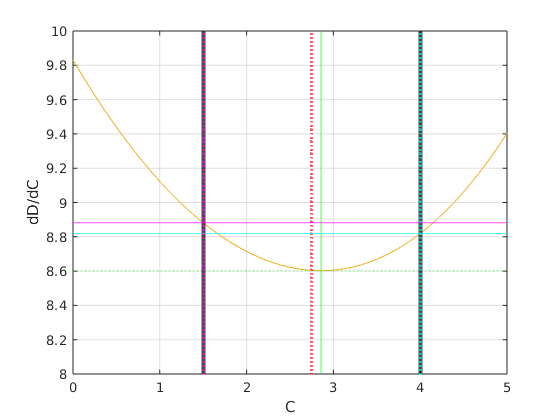

% and choose the smallest minimum
xline(c,'m:','LineWidth',2); yline(minDist,'m');

Or we can represent our constraints with a nonlinear function.

lb = 0; % entire range
ub = 5;
[c, minDist] = fmincon(@costFunc, 0, [], [], [], [], lb, ub, @nlconstr, [])


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


c = 1.5000

minDist = 8.8818

% stops at 1.5!
plot(c,minDist,'mo','MarkerSize',12);

Q) Why did this return the minimum at $C=1\ldotp 5$?

A) This is a LOCAL minimum! We started searching at $C_0 =0\ldotp 0$, and recall that the initial guess is important.

Try again with initial guess $C_0 =5\ldotp 0$...

[c, minDist] = fmincon(@costFunc, 5, [], [], [], [], lb, ub, @nlconstr, [])


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


c = 4.0000

minDist = 8.8191

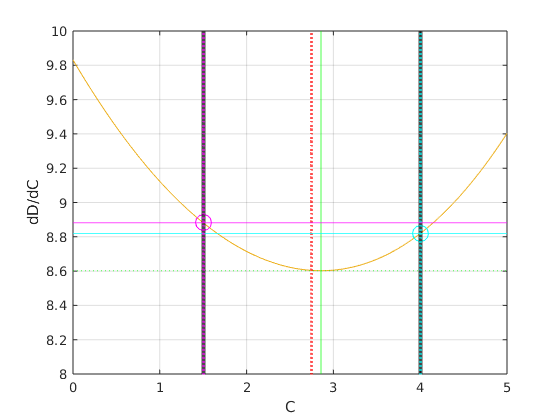

% stops at 4!
plot(c,minDist,'co','MarkerSize',12);

Finally, let's try UNCONSTRAINED optimization with `fminsearch` and an AUGMENTED cost function.

(Slide 9)

Remember that the initial guess still matters!

Try searching with initial guess $C_0 =0\ldotp 0$...

[c, minDist] = fminsearch(@augCost, 0)

c = 1.4999

minDist = 8.8818

% stops at 1.5!
plot(c,minDist,'mx','MarkerSize',16);


Try searching with initial guess $C_0 =3\ldotp 0$...

[c, minDist] = fminsearch(@augCost, 3)

c = 2.8572

minDist = 1.0009e+04

% stops at relative local minimum, despite huge cost!
plot(c,sqrt(a^2 + c.^2)+sqrt(b^2 + (d-c).^2),'rx','MarkerSize',16);


Try searching with initial guess $C_0 =5\ldotp 0$...

[c, minDist] = fminsearch(@augCost, 5)

c = 4

minDist = 8.8191

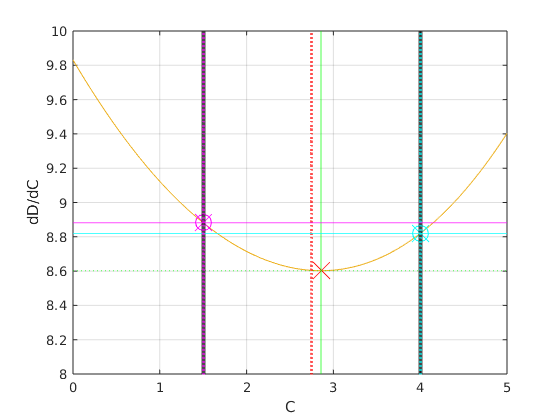

% stops at relative local minimum, despite huge cost!
plot(c,minDist,'cx','MarkerSize',16);

Augmented cost function for `fmincon.` It increases the cost for candidate solutions that fall within the "forbidden zone!"

function out = augCost(C)

    global a b d
    
    r1 = sqrt(a^2 + C.^2);
    r2 = sqrt(b^2 + (d-C).^2);
    out = r1 + r2;
    
    c1 = C - 1.5;
    c2 = -C + 4;
    
    P = max(0,[c1;c2]);
    
    if C > 1.5 && C < 4.0
        out = out + 10000;
    end

end


Nonlinear constraint function for `fmincon.` Note that this function must return both **equality** and **inequality **constraints (but you can leave one empty).

This function uses a trick! Recall the linear inequalities we used before: $\textrm{Ax}\le b$


$$\begin{array}{l}
C\le 1\ldotp 5\\
C\ge 4\ldotp 0\longrightarrow -C\le -4\ldotp 0
\end{array}$$


User-defined nonlinear constraints must have the form: $c\left(x\right)\le 0$


$$c_1 \left(x\right)\;=\;C-1\ldotp 5$$

$$\le 0$$



$$c_2 \left(x\right)=-C+4\ldotp 0$$

$$\le 0$$


Now for the trick! Use the nonlinear function `min(`$c_1 \left(x\right)\;$, $c_2 \left(x\right)$`)` to OR them together (Since constraint violations are positive numbers. 

function [constr,eqconstr] = nlconstr(C)
    
    eqconstr = [];
    
    c1 = C - 1.5;
    c2 = -C + 4;
    constr = min(c1,c2);

end

Cost function for `fminsearch` and `fmincon`

function dist = costFunc(C)

    global a b d
    
    r1 = sqrt(a^2 + C.^2);
    r2 = sqrt(b^2 + (d-C).^2);
    dist = r1 + r2;
    
end

Necessary condition for `fzero`


% for fzero
function error = necessaryCondition(C)
    a = 2;
    b = 3;
    d = 5;
    
    r1 = sqrt(a^2 + C.^2);
    r2 = sqrt(b^2 + (d-C).^2);
    D = r1 + r2;
    
    drA_dC = (1/2)*(1./sqrt(a^2 + C.^2)).*(2*C);
    drB_dC = (1/2)*(1./sqrt(b^2 + (d-C).^2))*2.*(d-C)*(-1);
    
    error = drA_dC + drB_dC;
    
end